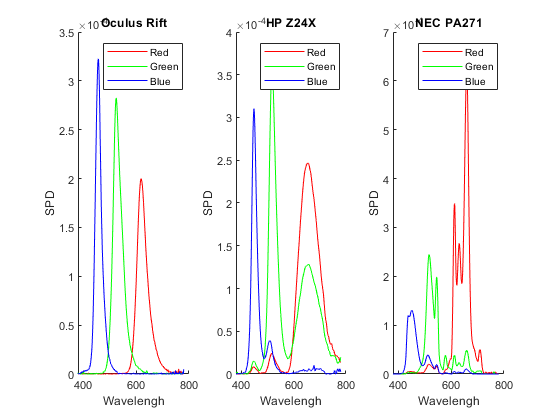

clf

subplot(1,3,1)
rs.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('Oculus Rift')

subplot(1,3,2)
hp.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('HP Z24X')

subplot(1,3,3)
nec.show_spectra
xlabel('Wavelengh')
ylabel('SPD')
title('NEC PA271')


saveas(gcf,'compare3spectra.png')



srgb = [0.64 0.33; 0.3 0.6 ; 0.15 0.06];
p3 = [0.68 0.32; 0.265 0.69 ; 0.15 0.06];
rec2020 = [0.708 0.292; 0.170 0.797 ; 0.131 0.046];

cc = ColorConversionClass;


clf
hold on
plot(srgb([1 2 3 1],1),srgb([1 2 3 1],2),':')
plot(p3([1 2 3 1],1),p3([1 2 3 1],2),':')
plot(rec2020([1 2 3 1],1),rec2020([1 2 3 1],2),':')

dp = rs

dp =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.0800
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []


XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')


dp = nec

dp =   NECPA271Sim with properties:

            sc: 0.0700
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []


XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')

dp = hp

dp =   HPZ24xSim with properties:

            sc: 0.0700
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: [256×2 double]


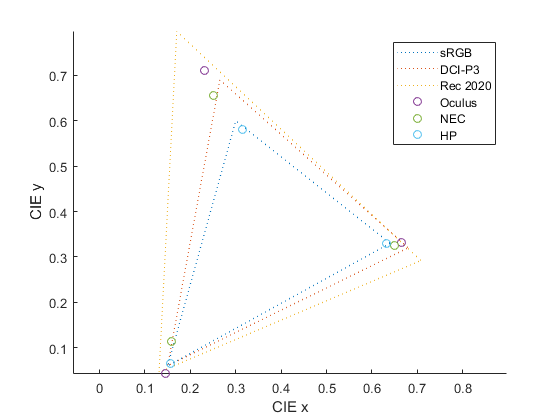

XYZ_r = cc.spd2XYZ(dp.spec_r(1:10:end)');
XYZ_g = cc.spd2XYZ(dp.spec_g(1:10:end)');
XYZ_b = cc.spd2XYZ(dp.spec_b(1:10:end)');

xyz_r = XYZ_r / sum(XYZ_r);
xyz_g = XYZ_g / sum(XYZ_g);
xyz_b = XYZ_b / sum(XYZ_b);

plot([xyz_r(1) xyz_g(1) xyz_b(1) xyz_r(1)],[xyz_r(2) xyz_g(2) xyz_b(2) xyz_r(2)],'o')



axis equal
xlabel('CIE x')
ylabel('CIE y')


legend('sRGB','DCI-P3','Rec 2020','Oculus','NEC','HP')